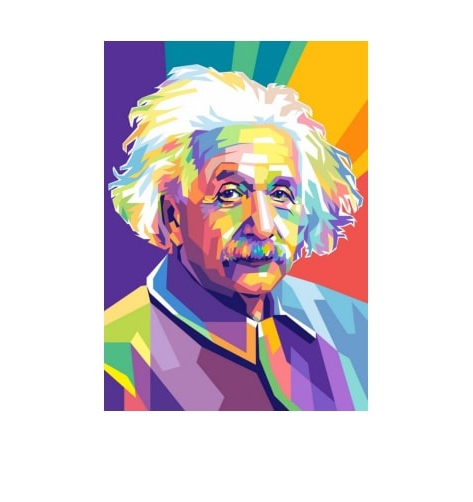

original_image = imread('download.jpg');
imshow(original_image)

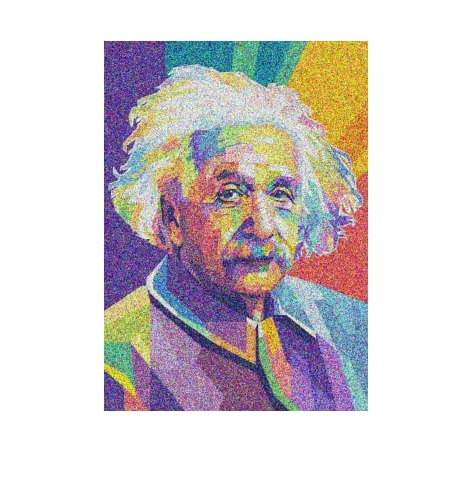




noisy_image = imread('noisy_image.jpg');
imshow(noisy_image)

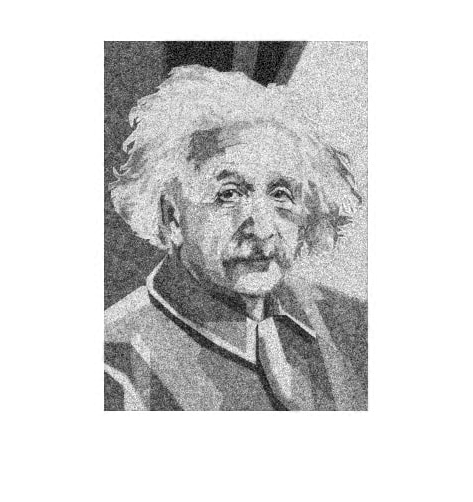




R0 = noisy_image(:,:,1);
G0 = noisy_image(:,:,2);
B0 = noisy_image(:,:,3);




imshow(R0);

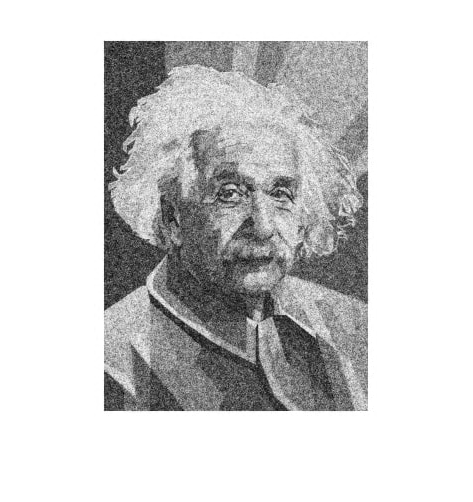

imshow(G0);

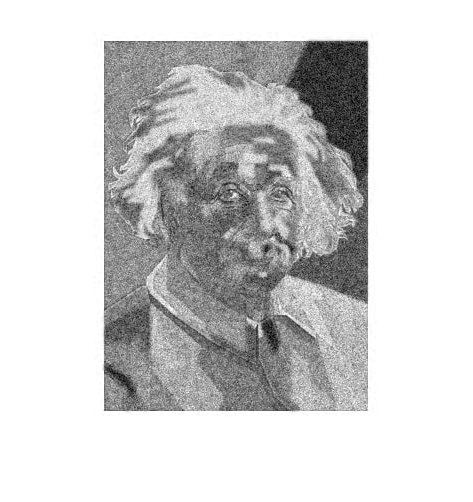

imshow(B0);

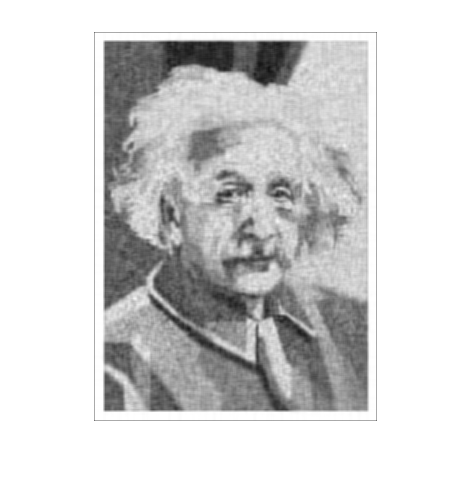


R = double(R0);
G = double(G0);
B = double(B0);



[Ur, Sr, Vr] = svd(R);
[Ug, Sg, Vg] = svd(G);
[Ub, Sb, Vb] = svd(B);

X_r = 800;
X_g = 800;
X_b = 800;


Sr(Sr < X_r) = 0;
Sg(Sg < X_g) = 0;
Sb(Sb < X_b) = 0;

reconstructed_r = uint8(Ur*Sr*(Vr)');
reconstructed_g = uint8(Ug*Sg*(Vg)');
reconstructed_b = uint8(Ub*Sb*(Vb)');


Kaverage_r = filter2(fspecial('average',3),reconstructed_r)/255;
imshow(Kaverage_r)

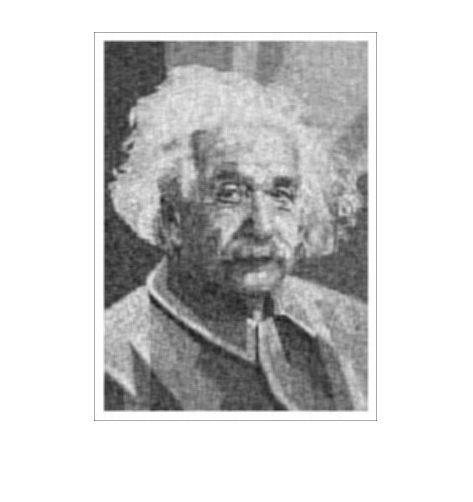


Kaverage_g = filter2(fspecial('average',3),reconstructed_g)/255;
imshow(Kaverage_g)


Kaverage_b = filter2(fspecial('average',3),reconstructed_b)/255;
imshow(Kaverage_g)

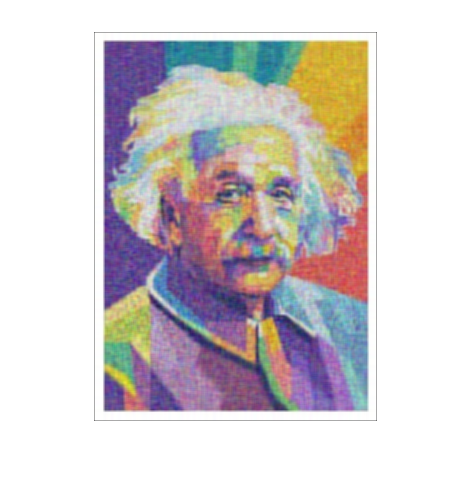




denoised_image = cat(3,Kaverage_r ,Kaverage_g,Kaverage_b);
imshow(denoised_image)

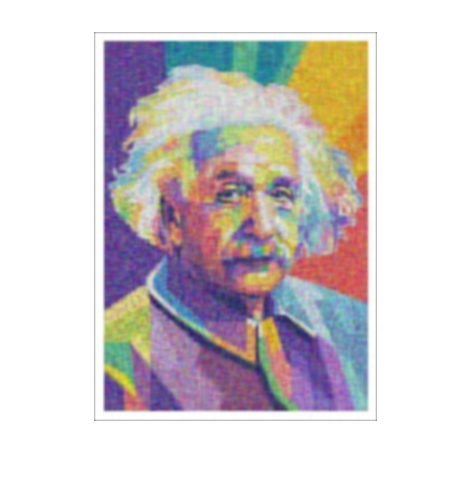



smooth_image = imgaussfilt(denoised_image,0.8);
imshow(smooth_image)